%pathtool alllows you to add new paths with subfolders etc. 
%helpful for when you have a lot of data


home
tc=130 %learned how to use one of those cute slider things (:

tc = 130

scale_factor=9/5

scale_factor = 1.8000

offset_factor=32

offset_factor = 32

TF=cent2fahr_v3(tc,scale_factor,offset_factor)

TF = 266

global scale offset %Dave says "DON'T USE GLOBAL >:("
scale=9/5;
offset=32;
TF=cent2fahr_v4(10)

TF = 50

scale 

scale = NaN

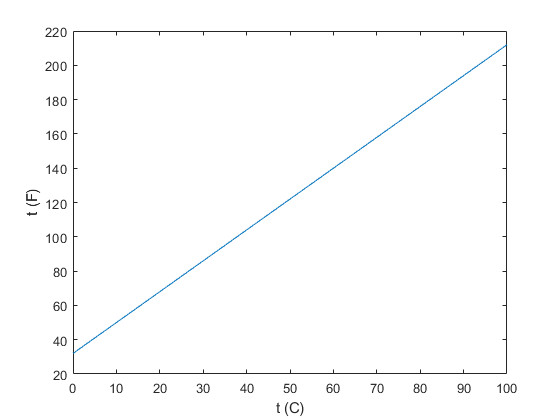

scale_factor=9/5;
offset_factor=32;
TC=0:100;
TF=cent2fahr_v3(TC,scale_factor,offset_factor);
figure(1)
plot(TC,TF)
xlabel('t (C)'); ylabel('t (F)'); %lol I tried to run but there are semicolons I'm stupid.

tc=10;
c2f=@(TC) TC*scale_factor+offset_factor; %c2f is the name of the anonymous function = @ arguments. Space, define function
TF_anonymous=c2f(tc)

TF_anonymous = 50

%first main message is the idea of functions
%looked at the homework, I'm FUCKED for this week
%if I believe in god will they make me good at coding? 

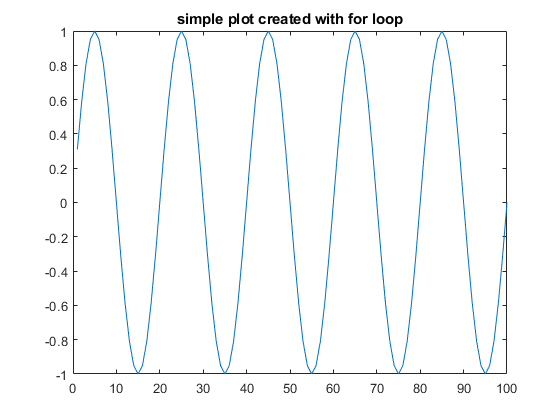

for n=1:100 %for statement, looping variable (n) and range (1:100)
    x(n)=sin(n*pi/10); %auto-indents while part of a for loop
end
figure(1)
plot(x)
title('simple plot created with for loop')

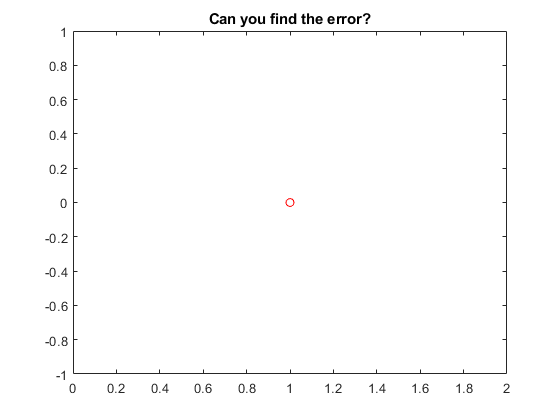

for n=1:100
    x=sin(n*pi/10); %didnt add n, so no loop variable. This mistake is for dummies
end
figure(2)
plot(x,'ro')     %what happened here?
title('Can you find the error?')

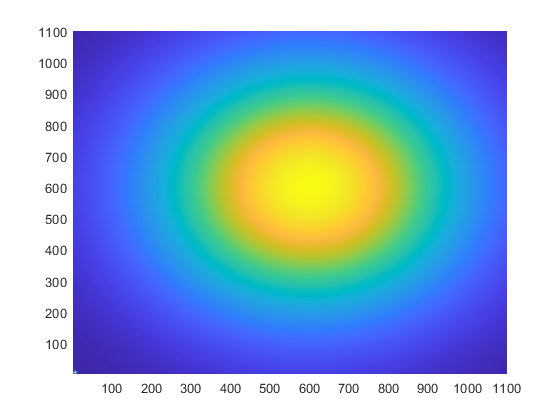

tic
for x=1:11
    for y=1:11
        z(x,y)=exp(-((x-6)/4)^2-((y-6)/4)^2);
    end
end
figure(3)
pcolor(z);
shading flat


toc %So, the elapsed time between tic and toc will print to the screen

Elapsed time is 0.029819 seconds.


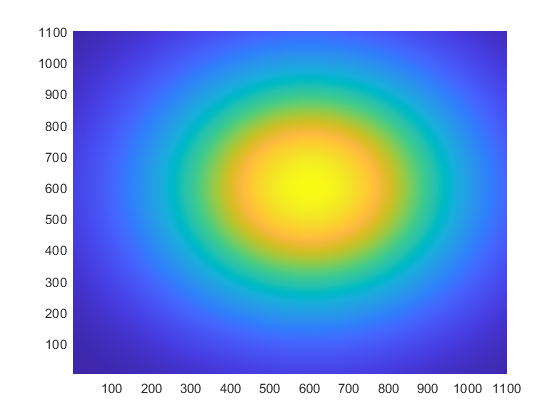

tic
for x=1:1100
    for y=1:1100
        z(x,y)=exp(-((x-600)/400)^2-((y-600)/400)^2);
    end
end
figure(4)
pcolor(z); shading flat

toc

Elapsed time is 0.076730 seconds.


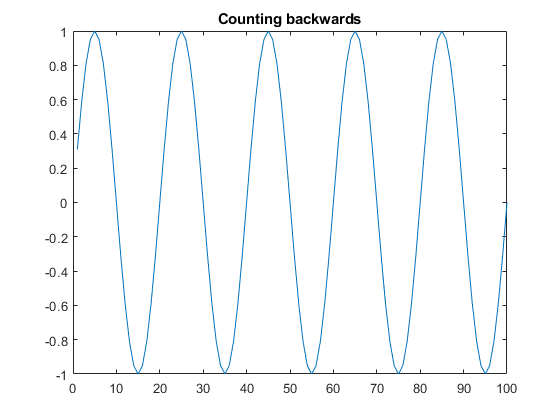

for n=100:-1:1 %this allows you to count backwards (start high go low) 
    x(n)=sin(n*pi/10);
end
figure(5)
plot(x)
title('Counting backwards')

%Dave says 4-tran a lot and it sounds like 4-chan and it's reallllly funny
%for loops are for a defined number of times

While Loops

n=1;
while n<10
    disp(['n = ' num2str(n)])
    n=n+1;
end

n = 1
n = 2
n = 3
n = 4
n = 5
n = 6
n = 7
n = 8
n = 9


n=1;
while n<10
    disp(['n = ' num2str(n)])
end; %DONT RUN, the increments were not defined here (n+1) so its an infinate 1 loop. Yike
%while is when you don't KNOW the defined number of times 
%a break command will kill a loop, good if your code is broken \

If Loops

%if statements arent loops
f=6

f = 6

%check if f is even
if mod(f,2)==0 %if something is equal to something else, use == 
    disp('f is even')
end

f is even


f=5

f = 5

%check if f is even
if mod(f,2)==0
    disp('f is even')
else
    disp('f is odd')
end

f is odd


Switch

%just look at class notes.  Not super different than if/else, but you use
%exact values and can't use functions/equations 